# Reporte R03

## Integrantes

- Fabián Carrasco Yahadad David

- Flores Vázquez Elvin

- Tenorio Camacho Javier

- Palma Mejía Luis Adrián

## Problema 2

Implementación de un FIS de tipo-II  como se encuentra en la siguiente página: [Fuzzy PID Control with Type-2 FIS](https://www.mathworks.com/help/fuzzy/fuzzy-pid-control-with-type-2-fis.html#FuzzyPIDControlWithType2FISExample-3).

clear all, close all, clc
%Creación de un sistema FIS de tipo-II
fis1 = sugfistype2

fis1 =   sugfistype2 with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "probor"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
                     Inputs: [0×0 fisvar]
                    Outputs: [0×0 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0
        TypeReductionMethod: "karnikmendel"

	See 'getTunableSettings' method for parameter optimization.


%Definición de las entradas junto con sus variables lingüisticas y funciones de membresía (Tipo-I).
fis1 = addInput(fis1,[-1 1],'Name','E');
fis1 = addInput(fis1,[-1 1],'Name','delE');

fis1 = addMF(fis1,'E','trimf',[-2 -1 0],'Name','N');
fis1 = addMF(fis1,'E','trimf',[-1 0 1],'Name','Z');
fis1 = addMF(fis1,'E','trimf',[0 1 2],'Name','P');
fis1 = addMF(fis1,'delE','trimf',[-2 -1 0],'Name','N');
fis1 = addMF(fis1,'delE','trimf',[-1 0 1],'Name','Z');
fis1 = addMF(fis1,'delE','trimf',[0 1 2],'Name','P');

%Definición de la salida
fis1 = addOutput(fis1,[-1 1],'Name','U')

fis1 =   sugfistype2 with properties:

                       Name: "fis"
                  AndMethod: "prod"
                   OrMethod: "probor"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0
        TypeReductionMethod: "karnikmendel"

	See 'getTunableSettings' method for parameter optimization.


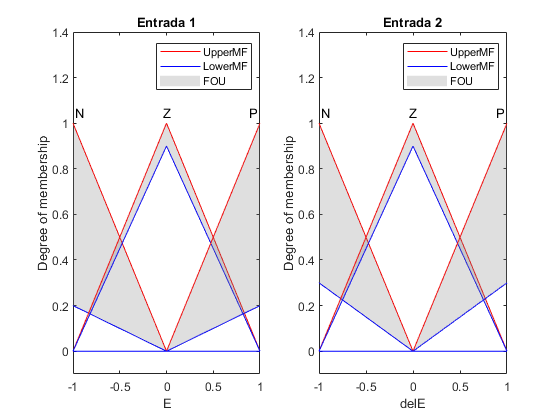

%Definición de la función de membresía (Tipo-I)de la salida y sus variables lingüisticas.
fis1 = addMF(fis1,'U','constant',-1,'Name','NB');
fis1 = addMF(fis1,'U','constant',-0.5,'Name','NM');
fis1 = addMF(fis1,'U','constant',0,'Name','Z');
fis1 = addMF(fis1,'U','constant',0.5,'Name','PM');
fis1 = addMF(fis1,'U','constant',1,'Name','PB');

%Definición de las reglas de inferencia difusa
rules = [...
    "E==N & delE==N => U=NB"; ...
    "E==Z & delE==N => U=NM"; ...
    "E==P & delE==N => U=Z"; ...
    "E==N & delE==Z => U=NM"; ...
    "E==Z & delE==Z => U=Z"; ...
    "E==P & delE==Z => U=PM"; ...
    "E==N & delE==P => U=Z"; ...
    "E==Z & delE==P => U=PM"; ...
    "E==P & delE==P => U=PB" ...
    ];
fis1 = addRule(fis1,rules);

%Conversión de funciones de membresía Tipo-I de las entradas en funciones de membresía difusas Tipo-II añadiendoles funciones de membresía inferiores.
scale = [0.2 0.9 0.2;0.3 0.9 0.3];
for i = 1:length(fis1.Inputs)
    for j = 1:length(fis1.Inputs(i).MembershipFunctions)
        fis1.Inputs(i).MembershipFunctions(j).LowerLag = 0;
        fis1.Inputs(i).MembershipFunctions(j).LowerScale = scale(i,j);
    end
end

%Visualización de las funciones de membresía Tipo-II de las entradas.
figure
subplot(1,2,1)
plotmf(fis1,'input',1)
title('Entrada 1')
subplot(1,2,2)
plotmf(fis1,'input',2)
title('Entrada 2')

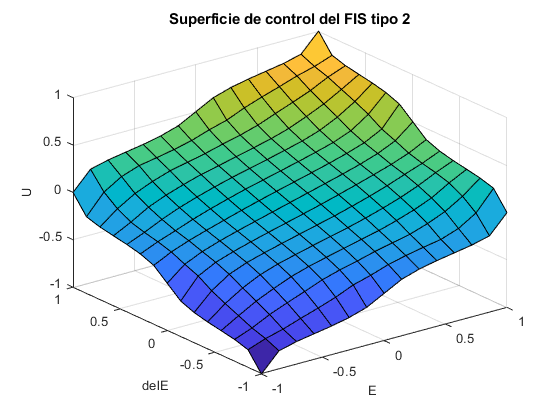

%Visualización de las funciones de membresía Tipo-II de las entradas.
figure
gensurf(fis1)
title('Superficie de control del FIS tipo 2')